## 1 image

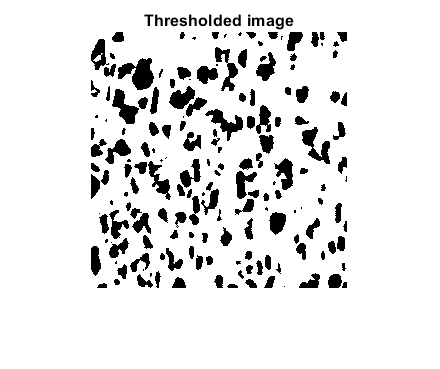

[result1,threshold1] = t2t("aluminium.png");
imshow(result1)
title('Thresholded image');

disp(['Obtained threshold value: ' num2str(threshold1)]);

Obtained threshold value: 104


## 2 image

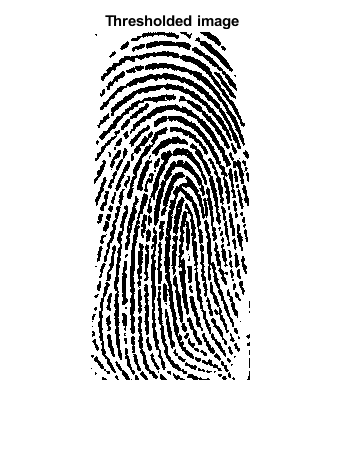

[result2,threshold2] = t2t("finger.png");
imshow(result2)
title('Thresholded image');

disp(['Obtained threshold value: ' num2str(threshold2)]);

Obtained threshold value: 159


## 3 image

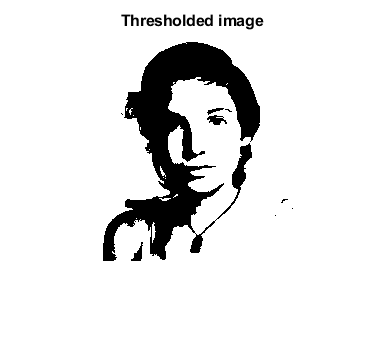

[result3,threshold3] = t2t("julia.png");
imshow(result3)
title('Thresholded image');

disp(['Obtained threshold value: ' num2str(threshold3)]);

Obtained threshold value: 150


## 4 image

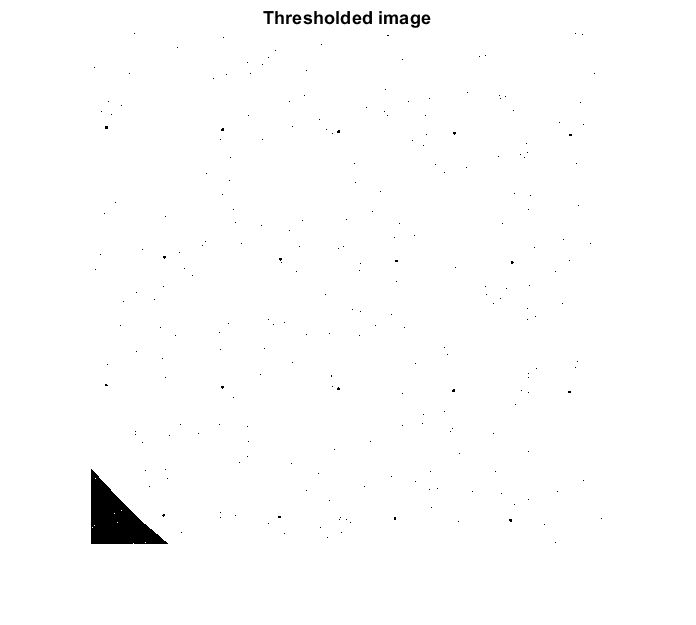

[result4,threshold4] = t2t("phobos.png");
imshow(result4)
title('Thresholded image');

disp(['Obtained threshold value: ' num2str(threshold4)]);

Obtained threshold value: 63


export("t2.mlx");

## Main function

function [result,threshold] = t2t(imagename)
I = imread(imagename);
I = uint8(I);

histogram_val = zeros(1, 256);

for i = 1:size(I, 1)
    for j = 1:size(I, 2)
        tmp = I(i, j) + 1;
        histogram_val(1, tmp) = histogram_val(1, tmp) + 1;
    end
end

S = sum(histogram_val, 2);

P = zeros(1,256);
for i = 1:256
    P(1, i) = histogram_val(1, i) / S;
end

mean = 0;
for i = 1:256
    mean = mean + i * P(1, i); 
end

variance = 0;
for i = 1:256
    variance = variance + (i - mean)^2 * P(1, i);
end

q1 = zeros(1,256);
q2 = zeros(1,256);

q1(1, 1) = P(1, 1);
q2(1, 1) = 1 - q1(1, 1);

for t = 2:256
    q1(1, t) = q1(1, t-1) + P(1, t);
    q2(1, t) = 1 - q1(1, t);
end

mean1 = zeros(1, 256);
mean1(1, 1) = 0;
for t = 2:256
    top = q1(1, t-1) * mean1(1, t-1) + t * P(1, t);
    bottom = q1(1, t);
    
    if(top == 0 && bottom == 0)
        continue;
    else
        mean1(1, t) = top / bottom;
    end
end

mean2 = zeros(1, 256);
mean2(1, 1) = 0;
for t = 2:256
    top = mean - q1(1, t) * mean1(1, t);
    bottom = 1 - q1(1, t);
    
    if(top == 0 && bottom == 0)
        continue;
    else
        mean2(1, t) = top / bottom;
    end
end

max_variance = -100; 
for t = 1:256
    variance_B = q1(1, t) * q2(1, t) * ((mean1(1, t) - mean2(1, t))^2);
    
    if(variance_B > max_variance)
        max_variance = variance_B;
        threshold = t;
    end
end

result = I;
for i = 1:size(result, 1)
    for j = 1:size(result, 2)
        if(result(i,j)<=threshold)
            result(i,j) = 0;
        else
            result(i,j) = 255;
        end
    end
end
end